# Single Image Super-Resolution Using Deep Learning

This example shows how to estimate a high-resolution image from a low-resolution image using a very-deep super-resolution (VDSR) neural network.

Super-resolution is the process of creating high-resolution images from low-resolution images. This example considers single image super-resolution (SISR), where the goal is to recover one high-resolution image from one low-resolution image. SISR is challenging because high-frequency image content typically cannot be recovered from the low-resolution image. Without high-frequency information, the quality of the high-resolution image is limited. Further, SISR is an ill-posed problem because one low-resolution image can yield several possible high-resolution images.

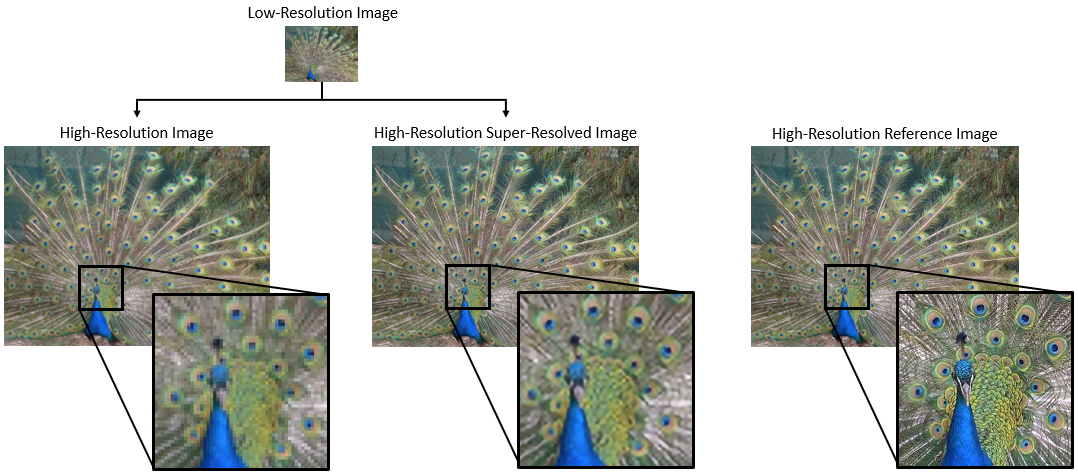

Several techniques, including deep learning algorithms, have been proposed to perform SISR. This example explores one deep learning algorithm for SISR, called very-deep super-resolution (VDSR) [1].

## The VDSR Network

VDSR is a convolutional neural network architecture designed to perform single image super-resolution [1]. The VDSR network learns the mapping between low- and high-resolution images. This mapping is possible because low-resolution and high-resolution images have similar image content and differ primarily in high-frequency details.

VDSR employs a residual learning strategy, meaning that the network learns to estimate a residual image. In the context of super-resolution, a residual image is the difference between a high-resolution reference image and a low-resolution image that has been upscaled using bicubic interpolation to match the size of the reference image. A residual image contains information about the high-frequency details of an image.

The VDSR network detects the residual image from the luminance of a color image. The luminance channel of an image, `Y`, represents the brightness of each pixel through a linear combination of the red, green, and blue pixel values. In contrast, the two chrominance channels of an image, *Cb* and *Cr*, are different linear combinations of the red, green, and blue pixel values that represent color-difference information. VDSR is trained using only the luminance channel because human perception is more sensitive to changes in brightness than to changes in color. 

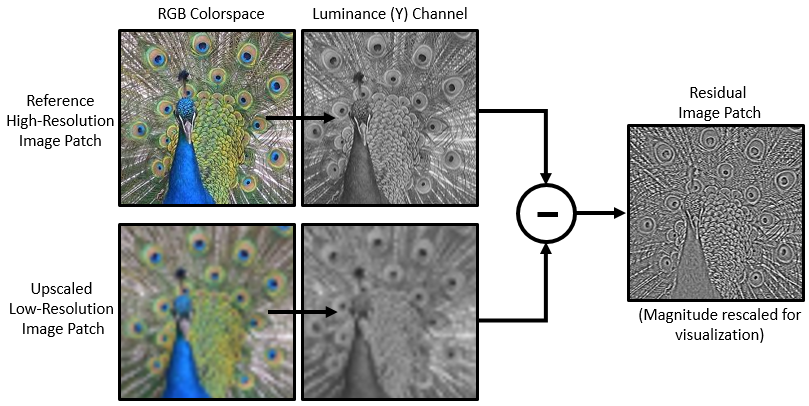

If $Y_{\textrm{high}\textrm{res}}$ is the luminance of the high-resolution image and $Y_{\textrm{lowres}}$ is the luminance a low-resolution image that has been upscaled using bicubic interpolation, then the input to the VDSR network is $Y_{\textrm{lowres}}$ and the network learns to predict  $Y_{\textrm{residual}} \;=\;Y_{\textrm{highres}} -Y_{\textrm{lowres}}$ from the training data. 

After the VDSR network learns to estimate the residual image, you can reconstruct high-resolution images by adding the estimated residual image to the upsampled low-resolution image, then converting the image back to the RGB color space.

A scale factor relates the size of the reference image to the size of the low-resolution image. As the scale factor increases, SISR becomes more ill-posed because the low-resolution image loses more information about the high-frequency image content. VDSR solves this problem by using a large receptive field. This example trains a VDSR network with multiple scale factors using scale augmentation. Scale augmentation improves the results at larger scale factors because the network can take advantage of the image context from smaller scale factors. Additionally, the VDSR network can generalize to accept images with noninteger scale factors.

## Download Training and Test Data

Download the IAPR TC-12 Benchmark, which consists of 20,000 still natural images [2]. The data set includes photos of people, animals, cities, and more. The size of the data file is ~1.8 GB. If you do not want to download the training data set, then you can load the pretrained VDSR network by typing `load('trainedVDSR-Epoch-100-ScaleFactors-234.mat');` at the command line. Then, go directly to the Perform Single Image Super-Resolution Using VDSR Network section in this example.

Use the helper function, `downloadIAPRTC12Data`, to download the data. This function is attached to the example as a supporting file. 

imagesDir = tempdir;
url = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
downloadIAPRTC12Data(url,imagesDir);

This will take several minutes to download and unzip...


다음 사용 중 오류가 발생함: matlab.internal.webservices.HTTPConnector/copyContentToFile (389번 라인)
URL 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz'에 액세스하는 중에 사용자에 의해 웹 서비스 작업이 종료되었습니다.

오류 발생: websave (

This example will train the network with a small subset of the IAPR TC-12 Benchmark data. Load the imageCLEF training data. All images are 32-bit JPEG color images.

trainImagesDir = fullfile(imagesDir,'iaprtc12','images','02');
exts = {'.jpg','.bmp','.png'};
pristineImages = imageDatastore(trainImagesDir,'FileExtensions',exts);

List the number of training images.

numel(pristineImages.Files)

## Prepare Training Data

To create a training data set, generate pairs of images consisting of upsampled images and the corresponding residual images.

The upsampled images are stored on disk as MAT files in the directory `upsampledDirName`. The computed residual images representing the network responses are stored on disk as MAT files in the directory `residualDirName`. The MAT files are stored as data type `double` for greater precision when training the network.

upsampledDirName = [trainImagesDir filesep 'upsampledImages'];
residualDirName = [trainImagesDir filesep 'residualImages'];

Use the helper function `createVDSRTrainingSet` to preprocess the training data. This function is attached to the example as a supporting file.

The helper function performs these operations for each pristine image in `trainImages`:

- Convert the image to the YCbCr color space

- Downsize the luminance (Y) channel by different scale factors to create sample low-resolution images, then resize the images to the original size using bicubic interpolation

- Calculate the difference between the pristine and resized images.

- Save the resized and residual images to disk.

scaleFactors = [2 3 4];
createVDSRTrainingSet(pristineImages,scaleFactors,upsampledDirName,residualDirName);

## Define Preprocessing Pipeline for Training Set

In this example, the network inputs are low-resolution images that have been upsampled using bicubic interpolation. The desired network responses are the residual images. Create an image datastore called `upsampledImages` from the collection of input image files. Create an image datastore called `residualImages` from the collection of computed residual image files. Both datastores require a helper function, `matRead`, to read the image data from the image files. This function is attached to the example as a supporting file.

upsampledImages = imageDatastore(upsampledDirName,'FileExtensions','.mat','ReadFcn',@matRead);
residualImages = imageDatastore(residualDirName,'FileExtensions','.mat','ReadFcn',@matRead);

Create an [`imageDataAugmenter`](docid:nnet_ref.mw_bb6aac9c-0a3d-4700-b4f9-82088d9ad021) that specifies the parameters of data augmentation. Use data augmentation during training to vary the training data, which effectively increases the amount of available training data. Here, the augmenter specifies random rotation by 90 degrees and random reflections in the *x-*direction.

augmenter = imageDataAugmenter( ...
    'RandRotation',@()randi([0,1],1)*90, ...
    'RandXReflection',true);

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) that performs randomized patch extraction from the upsampled and residual image datastores. Patch extraction is the process of extracting a large set of small image patches, or tiles, from a single larger image. This type of data augmentation is frequently used in image-to-image regression problems, where many network architectures can be trained on very small input image sizes. This means that a large number of patches can be extracted from each full-sized image in the original training set, which greatly increases the size of the training set. 

patchSize = [41 41];
patchesPerImage = 64;
dsTrain = randomPatchExtractionDatastore(upsampledImages,residualImages,patchSize, ...
    "DataAugmentation",augmenter,"PatchesPerImage",patchesPerImage);

The resulting datastore, `dsTrain`, provides mini-batches of data to the network at each iteration of the epoch. Preview the result of reading from the datastore.

inputBatch = preview(dsTrain);
disp(inputBatch)

## Set Up VDSR Layers

This example defines the VDSR network using 41 individual layers from Deep Learning Toolbox™, including:

- [`imageInputLayer`](docid:nnet_ref.mw_fcd2d9b1-ce25-49d1-9d06-b7cf41594ff4) - Image input layer

- [`convolutional2dLayer`](docid:nnet_ref.mw_2d97b6cd-f8aa-4fad-88d6-d34875484820) - 2-D convolution layer for convolutional neural networks

- [`reluLayer`](docid:nnet_ref.mw_ca5427bd-5cdc-4a58-ba63-302c257d8222) - Rectified linear unit (ReLU) layer

- [`regressionLayer`](docid:nnet_ref.bvlk3f6) - Regression output layer for a neural network

The first layer, `imageInputLayer`, operates on image patches. The patch size is based on the network receptive field, which is the spatial image region that affects the response of the top-most layer in the network. Ideally, the network receptive field is the same as the image size so that the field can see all the high-level features in the image. In this case, for a network with *D* convolutional layers, the receptive field is (2*D*+1)-by-(2*D*+1). 

VDSR has 20 convolutional layers so the receptive field and the image patch size are 41-by-41. The image input layer accepts images with one channel because VDSR is trained using only the luminance channel.

networkDepth = 20;
firstLayer = imageInputLayer([41 41 1],'Name','InputLayer','Normalization','none');

The image input layer is followed by a 2-D convolutional layer that contains 64 filters of size 3-by-3. The mini-batch size determines the number of filters. Zero-pad the inputs to each convolutional layer so that the feature maps remain the same size as the input after each convolution. He's method [3] initializes the weights to random values so that there is asymmetry in neuron learning. Each convolutional layer is followed by a ReLU layer, which introduces nonlinearity in the network.

convLayer = convolution2dLayer(3,64,'Padding',1, ...
    'WeightsInitializer','he','BiasInitializer','zeros','Name','Conv1');

Specify a ReLU layer.

relLayer = reluLayer('Name','ReLU1');

The middle layers contain 18 alternating convolutional and rectified linear unit layers. Every convolutional layer contains 64 filters of size 3-by-3-by-64, where a filter operates on a 3-by-3 spatial region across 64 channels. As before, a ReLU layer follows every convolutional layer.

middleLayers = [convLayer relLayer];
for layerNumber = 2:networkDepth-1
    convLayer = convolution2dLayer(3,64,'Padding',[1 1], ...
        'WeightsInitializer','he','BiasInitializer','zeros', ...
        'Name',['Conv' num2str(layerNumber)]);
    
    relLayer = reluLayer('Name',['ReLU' num2str(layerNumber)]);
    middleLayers = [middleLayers convLayer relLayer];    
end

The penultimate layer is a convolutional layer with a single filter of size 3-by-3-by-64 that reconstructs the image.

convLayer = convolution2dLayer(3,1,'Padding',[1 1], ...
    'WeightsInitializer','he','BiasInitializer','zeros', ...
    'NumChannels',64,'Name',['Conv' num2str(networkDepth)]);

The last layer is a regression layer instead of a ReLU layer. The regression layer computes the mean-squared error between the residual image and network prediction.

finalLayers = [convLayer regressionLayer('Name','FinalRegressionLayer')];

Concatenate all the layers to form the VDSR network.

layers = [firstLayer middleLayers finalLayers];

Alternatively, you can use the `vdsrLayers` helper function to create VDSR layers. This function is attached to the example as a supporting file.

layers = vdsrLayers;

## Specify Training Options

Train the network using stochastic gradient descent with momentum (SGDM) optimization. Specify the hyperparameter settings for SGDM by using the [`trainingOptions`](docid:nnet_ref.bu59f0q) function. The learning rate is initially `0.1` and decreased by a factor of 10 every 10 epochs. Train for 100 epochs.

Training a deep network is time-consuming. Accelerate the training by specifying a high learning rate. However, this can cause the gradients of the network to explode or grow uncontrollably, preventing the network from training successfully. To keep the gradients in a meaningful range, enable gradient clipping by specifying `'GradientThreshold'` as `0.01`, and specify `'GradientThresholdMethod'` to use the L2-norm of the gradients.

maxEpochs = 100;
epochIntervals = 1;
initLearningRate = 0.1;
learningRateFactor = 0.1;
l2reg = 0.0001;
miniBatchSize = 64;
options = trainingOptions('sgdm', ...
    'Momentum',0.9, ...
    'InitialLearnRate',initLearningRate, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',learningRateFactor, ...
    'L2Regularization',l2reg, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThresholdMethod','l2norm', ...
    'GradientThreshold',0.01, ...
    'Plots','training-progress', ...
    'Verbose',false);

## Train the Network

By default, the example loads a pretrained version of the VDSR network that has been trained to super-resolve images for scale factors 2, 3 and 4. The pretrained network enables you to perform super-resolution of test images without waiting for training to complete.

To train the VDSR network, set the `doTraining` variable in the following code to `true`. Train the network using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function.

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For more information, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Training takes about 6 hours on an NVIDIA Titan X.

doTraining = false;
if doTraining
    net = trainNetwork(dsTrain,layers,options);
    modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));
    save(strcat("trainedVDSR-",modelDateTime,"-Epoch-",num2str(maxEpochs),"-ScaleFactors-234.mat"),'net');
else
    load('trainedVDSR-Epoch-100-ScaleFactors-234.mat');
end

# Perform Single Image Super-Resolution Using VDSR Network

To perform single image super-resolution (SISR) using the VDSR network, follow the remaining steps of this example. The remainder of the example shows how to:

- Create a sample low-resolution image from a high-resolution reference image.

- Perform SISR on the low-resolution image using bicubic interpolation, a traditional image processing solution that does not rely on deep learning. 

- Perform SISR on the low-resolution image using the VDSR neural network.

- Visually compare the reconstructed high-resolution images using bicubic interpolation and VDSR.

- Evaluate the quality of the super-resolved images by quantifying the similarity of the images to the high-resolution reference image.

## Create Sample Low-Resolution Image

Create a low-resolution image that will be used to compare the results of super-resolution using deep-learning to the result using traditional image processing techniques such as bicubic interpolation. The test data set, `testImages`, contains 21 undistorted images shipped in Image Processing Toolbox™. Load the images into an `imageDatastore`.

exts = {'.jpg','.png'};
fileNames = {'sherlock.jpg','car2.jpg','fabric.png','greens.jpg','hands1.jpg','kobi.png', ...
    'lighthouse.png','micromarket.jpg','office_4.jpg','onion.png','pears.png','yellowlily.jpg', ...
    'indiancorn.jpg','flamingos.jpg','sevilla.jpg','llama.jpg','parkavenue.jpg', ...
    'peacock.jpg','car1.jpg','strawberries.jpg','wagon.jpg'};
filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
filePathNames = strcat(filePath,fileNames);
testImages = imageDatastore(filePathNames,'FileExtensions',exts);

Display the testing images as a montage.

montage(testImages)

Select one of the images to use as the reference image for super-resolution. You can optionally use your own high-resolution image as the reference image.

indx = 1; % Index of image to read from the test image datastore
Ireference = readimage(testImages,indx);
Ireference = im2double(Ireference);
imshow(Ireference)
title('High-Resolution Reference Image')

Create a low-resolution version of the high-resolution reference image by using [`imresize`](docid:matlab_ref#mw_32f88ffe-cee4-4dc6-a022-dcf048941b95) with a scaling factor of 0.25. The high-frequency components of the image are lost during the downscaling.

scaleFactor = 0.25;
Ilowres = imresize(Ireference,scaleFactor,'bicubic');
imshow(Ilowres)
title('Low-Resolution Image')

## Improve Image Resolution Using Bicubic Interpolation

A standard way to increase image resolution without deep learning is to use bicubic interpolation. Upscale the low-resolution image using bicubic interpolation so that the resulting high-resolution image is the same size as the reference image.

[nrows,ncols,np] = size(Ireference);
Ibicubic = imresize(Ilowres,[nrows ncols],'bicubic');
imshow(Ibicubic)
title('High-Resolution Image Obtained Using Bicubic Interpolation')

## Improve Image Resolution Using Pretrained VDSR Network

Recall that VDSR is trained using only the luminance channel of an image because human perception is more sensitive to changes in brightness than to changes in color.

Convert the low-resolution image from the RGB color space to luminance (`Iy`) and chrominance (`Icb` and `Icr`) channels by using the [`rgb2ycbr`](docid:images_ref.bvidgw5) function.

Iycbcr = rgb2ycbcr(Ilowres);
Iy = Iycbcr(:,:,1);
Icb = Iycbcr(:,:,2);
Icr = Iycbcr(:,:,3);

Upscale the luminance and two chrominance channels using bicubic interpolation. The upsampled chrominance channels, `Icb_bicubic` and `Icr_bicubic`, require no further processing.

Iy_bicubic = imresize(Iy,[nrows ncols],'bicubic');
Icb_bicubic = imresize(Icb,[nrows ncols],'bicubic');
Icr_bicubic = imresize(Icr,[nrows ncols],'bicubic');

Pass the upscaled luminance component, `Iy_bicubic`, through the trained VDSR network. Observe the [activations](docid:nnet_ref#mw_70f86305-04b8-41c4-9276-0d1a9bcb9e96) from the final layer (a regression layer). The output of the network is the desired residual image.

Iresidual = activations(net,Iy_bicubic,41);
Iresidual = double(Iresidual);
imshow(Iresidual,[])
title('Residual Image from VDSR')

Add the residual image to the upscaled luminance component to get the high-resolution VDSR luminance component.

Isr = Iy_bicubic + Iresidual;

Concatenate the high-resolution VDSR luminance component with the upscaled color components. Convert the image to the RGB color space by using the [`ycbcr2rgb`](docid:images_ref.bvier3p-1) function. The result is the final high-resolution color image using VDSR.

Ivdsr = ycbcr2rgb(cat(3,Isr,Icb_bicubic,Icr_bicubic));
imshow(Ivdsr)
title('High-Resolution Image Obtained Using VDSR')

## Visual and Quantitative Comparison

To get a better visual understanding of the high-resolution images, examine a small region inside each image. Specify a region of interest (ROI) using vector `roi` in the format [*x* *y* *width* *height*]. The elements define the x- and y-coordinate of the top left corner, and the width and height of the ROI.

roi = [320 30 480 400];

Crop the high-resolution images to this ROI, and display the result as a montage. The VDSR image has clearer details and sharper edges than the high-resolution image created using bicubic interpolation.

montage({imcrop(Ibicubic,roi),imcrop(Ivdsr,roi)})
title('High-Resolution Results Using Bicubic Interpolation (Left) vs. VDSR (Right)');

Use image quality metrics to quantitatively compare the high-resolution image using bicubic interpolation to the VDSR image. The reference image is the original high-resolution image, `Ireference`, before preparing the sample low-resolution image.

Measure the peak signal-to-noise ratio (PSNR) of each image against the reference image. Larger PSNR values generally indicate better image quality. See [`psnr`](docid:images_ref#bt5uhgi-1) for more information about this metric.

bicubicPSNR = psnr(Ibicubic,Ireference)
vdsrPSNR = psnr(Ivdsr,Ireference)

Measure the structural similarity index (SSIM) of each image. SSIM assesses the visual impact of three characteristics of an image: luminance, contrast and structure, against a reference image. The closer the SSIM value is to 1, the better the test image agrees with the reference image. See [`ssim`](docid:images_ref#bt5rkbx-1) for more information about this metric.

bicubicSSIM = ssim(Ibicubic,Ireference)
vdsrSSIM = ssim(Ivdsr,Ireference)

Measure perceptual image quality using the Naturalness Image Quality Evaluator (NIQE). Smaller NIQE scores indicate better perceptual quality. See [`niqe`](docid:images_ref.mw_b03fa30c-0102-4174-9335-bb29e4a663d0) for more information about this metric.

bicubicNIQE = niqe(Ibicubic)
vdsrNIQE = niqe(Ivdsr)

Calculate the average PSNR and SSIM of the entire set of test images for the scale factors 2, 3, and 4. For simplicity, you can use the helper function, `superResolutionMetrics`, to compute the average metrics. This function is attached to the example as a supporting file.

scaleFactors = [2 3 4];
superResolutionMetrics(net,testImages,scaleFactors);

VDSR has better metric scores than bicubic interpolation for each scale factor.

## References

[1] Kim, J., J. K. Lee, and K. M. Lee. "Accurate Image Super-Resolution Using Very Deep Convolutional Networks." *Proceedings of the IEEE**®** Conference on Computer Vision and Pattern Recognition*. 2016, pp. 1646-1654.

[2] Grubinger, M., P. Clough, H. Müller, and T. Deselaers. "The IAPR TC-12 Benchmark: A New Evaluation Resource for Visual Information Systems." *Proceedings of the OntoImage 2006 Language Resources For Content-Based Image Retrieval*. Genoa, Italy. Vol. 5, May 2006, p. 10.

[3] He, K., X. Zhang, S. Ren, and J. Sun. "Delving Deep into Rectifiers: Surpassing Human-Level Performance on ImageNet Classification." *Proceedings of the IEEE International Conference on Computer Vision*, 2015, pp. 1026-1034.

*Copyright 2018 The MathWorks, Inc.*